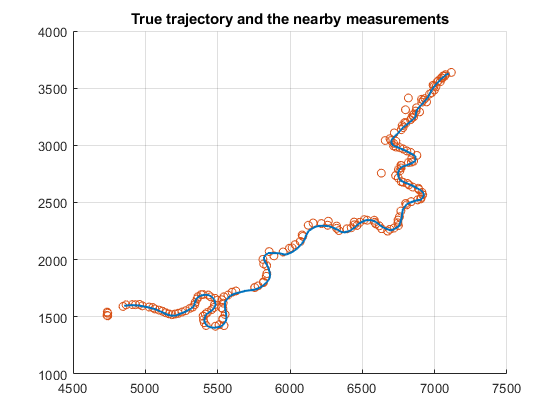

% load data
load joyridedata.mat;


% plot measurements close to the trajectory
figure(1); clf; hold on; grid on;
Zmat = cell2mat(Z');
Zplotdata = [];
plotMeasDist = 200;
for k = 1:K
   toPlot = false(size(Z{k},2),1);
   closecount(k) = 0;
   for j = 1:size(Z{k}, 2)
        v = Z{k}(:, j) - Xgt(1:2, k);
        toPlot(j) = v' * v <= plotMeasDist^2;
        if toPlot(j) 
            closecount(k) = closecount(k) + 1;
        end
   end
   Zplotdata = [Zplotdata, Z{k}(:, toPlot)];
end
set(gca, 'ColorOrderIndex', 2)
scatter(Zplotdata(1,:), Zplotdata(2,:));
set(gca, 'ColorOrderIndex', 1)
plot(Xgt(1,:),Xgt(2,:), 'LineWidth',1.5);
title('True trajectory and the nearby measurements')

% some minor data analysis for the interested person
i = 0;
maxdist = 30;
for k = 1:K
    if size(Z{k}, 2) > 0
        vall = Xgt(1:2,k) - Z{k};
        dsquared = sum((vall).^2, 1);
        closecount(k) = sum(dsquared <= maxdist^2);
        [mindist, ind] = min(dsquared);
        if mindist < maxdist^2
            i = i + 1;
            d(i) = mindist;
            v(:, i) = vall(:, ind);
        end
    end
end
stepsWithClose = i 

stepsWithClose = 136

meanMeasError = mean(v, 2)

meanMeasError =     3.6865
   -7.2491


covMeasError = cov(v')

covMeasError =   119.3970   14.9059
   14.9059  116.2221


stds = sqrt(diag(cov(v')))

stds =    10.9269
   10.7806


covEllSize = sqrt(eig(cov(v')))

covEllSize =    10.1400
   11.5239


meanMinMeasDists = mean(d)

meanMinMeasDists = 300.0264

meanNumberOfCloseMeasurements = mean(closecount)

meanNumberOfCloseMeasurements = 0.6800

% play measurement movie. Remember that you can click the stop button.
%{
figure(2); clf; grid on;
set(gcf,'Visible','on')
plotpause = 0.1; % sets a pause in between time steps if it goes to fast
minZ = min(Xgt(1:2, :), [], 2);
maxZ = max(Xgt(1:2, :), [], 2);
minZ = minZ - 0.05*(maxZ - minZ);
maxZ = maxZ + 0.05*(maxZ - minZ);
for k = 1:K
    scatter(Z{k}(1,:), Z{k}(2,:))
    title(sprintf('measurements at step %d', k))
    axis([minZ(1), maxZ(1), minZ(2), maxZ(2)])
    grid on;
    drawnow;
    pause(plotpause);
end
%}

% Look at individual EKF-PDAs

r = 10

r = 10

qCV = 0.001

qCV = 1.0000e-03

qCT = [0.005, 0.000025]

qCT =     0.0050    0.0000




PD = 0.95

PD = 0.9500

lambda = 1e-3

lambda = 1.0000e-03

gateSize = 5^2

gateSize = 25

% choose model to tune
s = 1;

% make models
models =  cell(2,1);
models{1} = EKF(discreteCVmodel(qCV, r));
models{2} = EKF(discreteCTmodel(qCT, r));

tracker =  cell(2,1);
tracker{1} = PDAF(models{1}, lambda, PD, gateSize);
tracker{2} = PDAF(models{2}, lambda, PD, gateSize);

% % % % allocate
xbar = zeros(5, K);
Pbar = zeros(5, 5, K);
xhat = zeros(5, K);
Phat = zeros(5, 5, K);
NEES = zeros(K, 1);
NEESpos = zeros(K, 1);
NEESvel = zeros(K, 1);

% initialize filter
xbar(:, 1) = [7100; 3630; -6; -3; 0]; % taken from ground truth
Pbar(:, : ,1) = diag(4*[10; 10; 1; 1; pi/10].^2); % seems reasonable?

% filter
for k = 1:K
    [xhat(:, k), Phat(:, :, k)] = tracker{s}.update(Z{k}, xbar(:, k), Pbar(:, :, k));
    %NEES(k) = %...
    %NEESpos(k) = %...
    %NEESvel(k) = %...
    if k < K
        [xbar(:, k+1), Pbar(:, :, k+1)] = tracker{s}.predict(xhat(:, k), Phat(:, :, k), Ts(k));
    end
end

% errors
poserr = sqrt(sum((xhat(1:2,:) - Xgt(1:2,:)).^2, 1));
posRMSE = sqrt(mean(poserr.^2));
velerr = sqrt(sum((xhat(3:4, :) - Xgt(3:4, :)).^2, 1));
velRMSE = sqrt(mean(velerr.^2));

% consistency
chi2inv([0.025, 0.975], K*2)/K

ans =     1.7324    2.2865


ANEESpos = mean(NEESpos)

ANEESpos = 0

ANEESvel = mean(NEESvel)

ANEESvel = 0

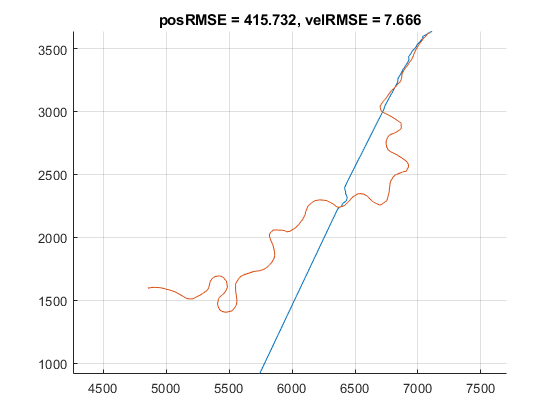

%ANIS = mean(NISes)

% plot
figure(3); clf; hold on; grid on;
plot(xhat(1,:), xhat(2,:));
plot(Xgt(1, :), Xgt(2, :))
%scatter(Zmat(1,:), Zmat(2, :), 'x');
axis('equal')
%scatter(Z(1,:), Z(2, :));
title(sprintf('posRMSE = %.3f, velRMSE = %.3f',posRMSE, velRMSE))

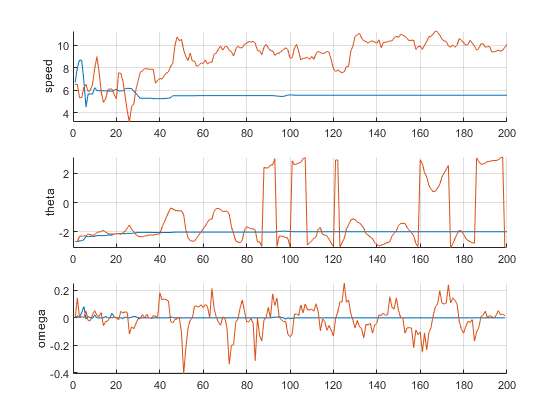


figure(4); clf; hold on; grid on;
subplot(3,1,1);
hold on; grid on;
plot(sqrt(sum(xhat(3:4,:).^2,1)))
plot(sqrt(sum(Xgt(3:4,:).^2,1)))
ylabel('speed')
subplot(3,1,2);
hold on; grid on;
plot(atan2(xhat(4,:), xhat(3,:)))
plot(atan2(Xgt(4,:), Xgt(3,:)))
ylabel('theta')
subplot(3,1,3)
hold on; grid on;
plot(diff(unwrap(atan2(xhat(4,:), xhat(3,:))))./Ts')
plot(diff(unwrap(atan2(Xgt(4,:), Xgt(3,:))))./Ts')
ylabel('omega')

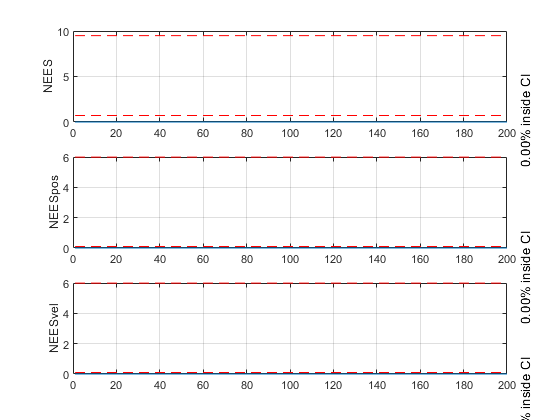


figure(5); clf;
subplot(3,1,1);
plot(NEES); grid on; hold on;
ylabel('NEES');
ciNEES = chi2inv([0.05, 0.95], 4);
inCI = sum((NEES >= ciNEES(1)) .* (NEES <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,2);
plot(NEESpos); grid on; hold on;
ylabel('NEESpos');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESpos >= ciNEES(1)) .* (NEESpos <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,3);
plot(NEESvel); grid on; hold on;
ylabel('NEESvel');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESvel >= ciNEES(1)) .* (NEESvel <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

% % IMM-PDA
% 
% % sensor 
% r = %...
% PD = %...
% lambda = %...
% gateSize = %...
% 
% % dynamic models
% qCV = %...
% qCT = %...
% qCVh = %...
% modIdx = 1:3; 
% M = numel(modIdx);
% 
% x0 = [7100; 3630; 0; 0; 0]; % taken from gt
% P0 = diag([25, 25, 10, 10, pi/6].^2); % seems reasonable?
% 
% % markov chain (other parameterizations can be simpler to tune)
% PI11 = %...
% PI22 = %...
% PI33 = %...
% 
% PI = %[PI11, ..., ...;
%     %..., PI22, ...;
%     %..., ..., PI33];
% 
% PI = PI(modIdx, modIdx) % select the models to use
% PI = PI./sum(PI,1); % be sure to normalize
% assert(all(sum(PI, 1) - 1 < eps),'columns of PI must sum to 1')
% 
% sprobs0 = %... 
% sprobs0 = sprobs0(modIdx)/sum(sprobs0(modIdx)) % select models and normalize
% assert(all(sprobs0 > 0), 'probabilities must be positive')
% 
% 
% % make model
% models =  cell(3,1);
% models{1} = EKF(discreteCVmodel(qCV, r));
% models{2} = EKF(discreteCTmodel(qCT, r));
% models{3} = EKF(discreteCVmodel(qCVh, r));
% imm = IMM(models(modIdx), PI);
% tracker = IMMPDAF(imm, lambda, PD, gateSize);
% 
% % allocate
% xbar = zeros(5, M, K);
% Pbar = zeros(5, 5, M, K);
% probbar = zeros(M, K);
% xhat = zeros(5, M, K);
% xest = zeros(5, K);
% Pest = zeros(5, 5, K);
% Phat = zeros(5, 5, M, K);
% probhat = zeros(M, K);
% NEES = zeros(K, 1);
% NEESpos = zeros(K, 1);
% NEESvel = zeros(K, 1);
% 
% % initialize
% xbar(:, :, 1) = repmat(x0, [1, M]); % simply same for all modes
% Pbar(:, : ,:, 1) = repmat(P0,[1,1,M]); %simply same for all modes
% probbar(:, 1) = sprobs0;
% 
% % filter
% for k=1:K
%     [probhat(:, k), xhat(:, :, k), Phat(:, :, :, k)] = %...
%     [xest(:, k), Pest(:, :, k)] = %...
%     
%     NEES(k) = %...
%     NEESpos(k) = %...
%     NEESvel(k) = %...  
%     if k < K
%         [probbar(:, k+1), xbar(:, :, k+1), Pbar(:, :, :, k+1)] = %...
%     end
% end
% 
% % errors
% poserr = sqrt(sum((xest(1:2,:) - Xgt(1:2,:)).^2, 1));
% posRMSE = sqrt(mean(poserr.^2)); % not true RMSE (which is over monte carlo simulations)
% velerr = sqrt(sum((xest(3:4, :) - Xgt(3:4, :)).^2, 1));
% velRMSE = sqrt(mean(velerr.^2)); % not true RMSE (which is over monte carlo simulations)
% peakPosDeviation = max(poserr);
% peakVelDeviation = max(velerr);
% 
% % consistency
% CI2K = chi2inv([0.025, 0.975], K*2)/K
% ANEESpos = mean(NEESpos)
% ANEESvel = mean(NEESvel)
% 
% CI4K = chi2inv([0.025, 0.975], K*4)/K
% ANEES = mean(NEES)
% 
% % plot
% figure(6); clf; hold on; grid on;
% plot(xest(1,:), xest(2,:));
% plot(Xgt(1,:), Xgt(2, :));
% scatter(Zmat(1,:), Zmat(2,:))
% axis('equal')
% title(sprintf('posRMSE = %.3f, velRMSE = %.3f, peakPosDev = %.3f, peakVelDev = %.3f',posRMSE, velRMSE, peakPosDeviation, peakVelDeviation))
% 
% figure(7); clf; hold on; grid on;
% subplot(3,1,1);
% hold on; grid on;
% plot(sqrt(sum(xest(3:4,:).^2,1)))
% plot(sqrt(sum(Xgt(3:4,:).^2,1)))
% ylabel('speed')
% subplot(3,1,2);
% hold on; grid on;
% plot(atan2(xest(4,:), xest(3,:)))
% plot(atan2(Xgt(4,:), Xgt(3,:)))
% ylabel('theta')
% subplot(3,1,3)
% hold on; grid on;
% plot(diff(unwrap(atan2(xest(4,:), xest(3,:))))./Ts')
% plot(diff(unwrap(atan2(Xgt(4,:), Xgt(3,:))))./Ts')
% ylabel('omega')
% 
% figure(8); clf;
% plot(probhat');
% grid on;
% 
% figure(9); clf;
% subplot(2,1,1); 
% plot(poserr); grid on;
% ylabel('position error')
% subplot(2,1,2);
% plot(velerr); grid on;
% ylabel('velocity error')
% 
% figure(10); clf;
% subplot(3,1,1);
% plot(NEES); grid on; hold on;
% ylabel('NEES');
% ciNEES = chi2inv([0.05, 0.95], 4);
% inCI = sum((NEES >= ciNEES(1)) .* (NEES <= ciNEES(2)))/K * 100;
% plot([1,K], repmat(ciNEES',[1,2])','r--')
% text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);
% 
% subplot(3,1,2);
% plot(NEESpos); grid on; hold on;
% ylabel('NEESpos');
% ciNEES = chi2inv([0.05, 0.95], 2);
% inCI = sum((NEESpos >= ciNEES(1)) .* (NEESpos <= ciNEES(2)))/K * 100;
% plot([1,K], repmat(ciNEES',[1,2])','r--')
% text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);
% 
% subplot(3,1,3);
% plot(NEESvel); grid on; hold on;
% ylabel('NEESvel');
% ciNEES = chi2inv([0.05, 0.95], 2);
% inCI = sum((NEESvel >= ciNEES(1)) .* (NEESvel <= ciNEES(2)))/K * 100;
% plot([1,K], repmat(ciNEES',[1,2])','r--')
% text(K*1.04, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

% %estimation "movie"
% mTL = 0.2; % maximum transparancy (between 0 and 1);
% plotpause = 1; % lenght to pause between time steps;
% plotRange = 2:K; % the range to go through
% N = 50; % number of points to use for ellipse;
% 
% %k = 31; assert(all([k > 1, k <= K]), 'K must be in proper range')
% figure(11); clf; grid on; hold on; axis equal;
% set(gcf,'Visible','on')
% co = get(gca, 'colorOrder');
% minAx = zeros(1,2);
% maxAx = 7000*ones(1,2);
% thetas = (0:N)*2*pi/N;
% for k = plotRange
%     % tracker
%     subplot(1,2,1);
%     cla; grid on; hold on; axis equal;
%     title(sprintf('time step %d', k));
%     gated = tracker.gate(Z{k}, probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
%     minG = 1e20 * ones(2,1);
%     maxG = -1e20 * ones(2,1);
%     [skupd, xkupd, Pkupd] = tracker.conditionalUpdate(Z{k}(:, gated), probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
%     beta = tracker.associationProbabilities(Z{k}(:, gated), probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
%     for s = 1:M
%         plot(squeeze(xhat(1, s, 1:(k-1))), squeeze(xhat(2, s, 1:(k-1)))','Color', co(s,:));
%         axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
%         for j = 1:size(xkupd, 3)
%             csj = mTL * co(s, :) + (1 - mTL) * (beta(j)*skupd(s, j)*co(s, :) + (1 - beta(j)*skupd(s, j)) * ones(1, 3)); % transparancy
%             pl = plot([squeeze(xhat(1, s, k-1)); xkupd(1, s, j)], [squeeze(xhat(2, s, k-1)); xkupd(2, s, j)], '--', 'Color', csj);
%             axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
%             %alpha(pl, beta(j)*skupd(s, j));
%             drawnow;
%             covEllData = chol(Pkupd(1:2,1:2, s, j))' * [cos(thetas); sin(thetas)] + xkupd(1:2, s, j);
%             pl = plot(covEllData(1, :), covEllData(2, :), '--', 'Color', csj);
%         end
%         
%         [vk, Sk] = imm.modeFilters{s}.innovation([0,0], squeeze(xbar(:, s, k)), squeeze(Pbar(:, :, s, k)));
%         gateData = chol(Sk)' * [cos(thetas); sin(thetas)] * sqrt(tracker.gateSize) + squeeze(xbar(1:2, s, k));
%         plot(gateData(1, :),gateData(2, :), '.--', 'Color', co(s,:))
%         scatter(Z{k}(1, :), Z{k}(2, :), 'rx')
%         
%         minGs = min(gateData, [], 2);
%         minG = minGs .* (minGs < minG) + minG .* (minG <= minGs);
%         maxGs = max(gateData, [], 2);
%         maxG = maxGs .* (maxGs > maxG) + maxG .* (maxG >= maxGs);
%         
%     end
%     scale = 1;
%     minAx = minG - scale * (maxG - minG);
%     maxAx = maxG + scale * (maxG - minG);
%     axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
%     %legend()
%     
%     % mode probabilities
%     subplot(1,2,2)
%     cla; grid on; hold on;
%     for s = 1:M
%         plot(probhat(s, 1:(k - 1)), 'Color', co(s, :));
%         for j = 1:size(xkupd, 3)
%             csj = mTL * co(s, :) + (1 - mTL) * (beta(j)*skupd(s, j)*co(s, :) + (1 - beta(j)*skupd(s, j)) * ones(1, 3)); % transparancy
%             plot([k-1, k], [probhat(s, k-1), skupd(s, j)], '--', 'color', csj)
%         end
%     end
%     axis([1, plotRange(end), 0, 1])
%     drawnow;
%     pause(plotpause)
% end